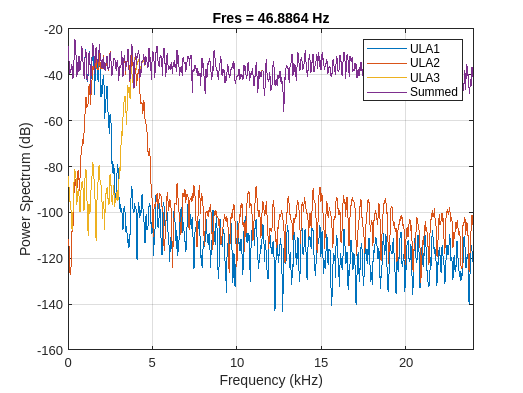

clear
close all
clc
data = load('log.DAS.20240506102844.txt'); % output af DAS
fs = 48e3;
t = 0:1/fs:(length(data)-1)/fs;
%plot(t,data)

output_ula1 = data(:,1);
output_ula2 = data(:,2);
output_ula3 = data(:,3);
output = data(:,4);

%plot(t,inputData)

% plot(t,output_ula1)
% hold on
% plot(t,output_ula2)
% plot(t,output_ula3)
% xlim([0.01 0.012])
% grid minor
% legend('input', 'output')
% title('Raw')
% hold off

% delayLength = 21; % HVORFOR 21??
% plot(t(1:end-delayLength),inputData(1:end-delayLength))
% hold on
% plot(t(1:end-delayLength),output_ula1(delayLength+1:end))
% xlim([0.0 0.002])
% grid minor
% legend('input', 'output')
% title('Offset')
% hold off

%spectrogram(inputData,fs)
%pwelch(inputData)
%pspectrum(inputData,fs)

pspectrum(output_ula1,fs)
hold on
pspectrum(output_ula2,fs)
pspectrum(output_ula3,fs)
pspectrum(output,fs)
legend('ULA1', 'ULA2', 'ULA3', 'Summed')
hold off

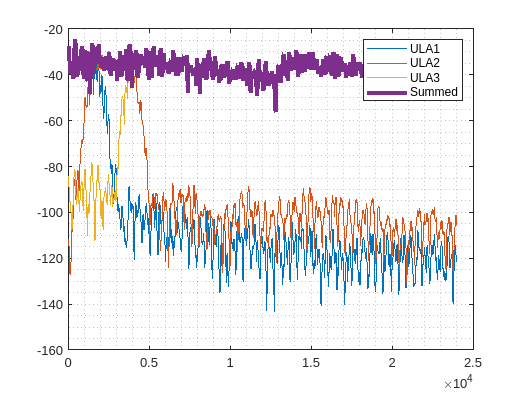


[p_ula1, f_ula1] = pspectrum(output_ula1,fs);
[p_ula2, f_ula2] = pspectrum(output_ula2,fs);
[p_ula3, f_ula3] = pspectrum(output_ula3,fs);
[p_sum, f_sum] = pspectrum(output,fs);


plot(f_ula1,10*log10(p_ula1))
hold on
plot(f_ula2,10*log10(p_ula2))
plot(f_ula3,10*log10(p_ula3))
plot(f_sum,10*log10(p_sum), 'LineWidth', 3)
legend('ULA1', 'ULA2', 'ULA3', 'Summed')
grid minor
hold off


%[pxx,f] = pwelch(output,[],[],[],fs);
% [pxx,f] = pspectrum(output,fs);
% plot(f,10*log10(pxx))


## yada

clear
close all
clc
data = load('log.DAS.20240506151251.txt');

angs = linspace(1,179,179)

angs =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


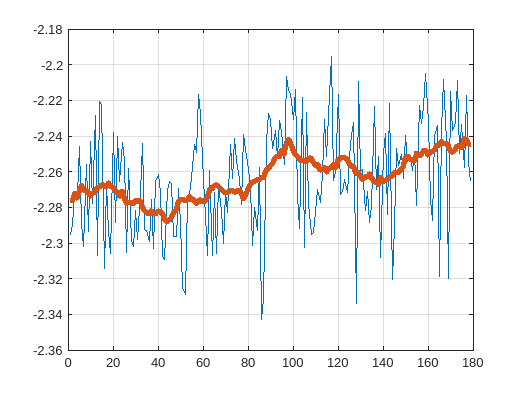

mags = data(:,2);
for i = 1:179
    mags_avg(i) = mean(data(find(data(:,1)==i),2));
end
plot(angs,10*log10(mags_avg))
hold on
plot(angs,movmean(10*log10(mags_avg),20),'LineWidth',4)
grid
hold off

## Yaydada

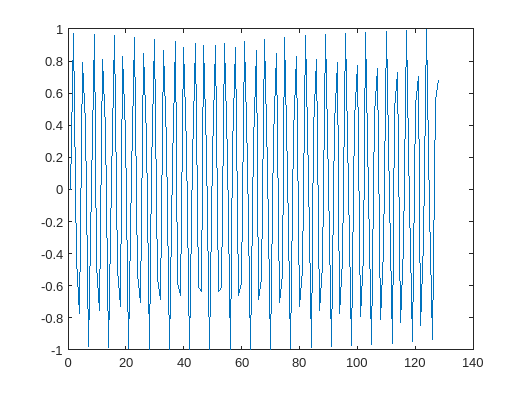

MIC_ARRAY = [0.0,    0.3750,    0.4583,    0.5000,    0.5417,    0.6250,    1.0];
sampling_frequency = 48e3; 
speed_of_sound = 1496;
input_sig_angle = 35;
samples_per_mic = 128;
for (j = 1:7)
    for (i = 1:samples_per_mic) 
        mic_inputs(i+(j-1)*samples_per_mic) = sin(2*pi*13750*((i-1)*1/sampling_frequency + MIC_ARRAY(j)*cos(input_sig_angle*pi/180.0)/speed_of_sound));
    end
end

plot(mic_inputs(1:samples_per_mic))